syms v(t) u(t) u_0
m = sym("m", "positive");
c = sym("c", "positive");
K = sym("K", "real");
r = sym("r", "real");


eq = m*diff(v,1) == u - c*v

$$eq(t) = m\,\frac{\partial }{\partial t}v\left(t\right)=u\left(t\right)-c\,v\left(t\right)$$

eq1 = subs(eq, u, u_0 )

$$eq1(t) = m\,\frac{\partial }{\partial t}v\left(t\right)=u_{0}-c\,v\left(t\right)$$

ans1b = dsolve(eq1, v(0)==0)

$$ans1b = \frac{u_{0}-u_{0}\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}$$

ans1a = limit(ans1b, t, inf)

$$ans1a = \frac{u_{0}}{c}$$

ans1b_example = subs(ans1b,[u_0, m, c],[1, 1, 1])

$$ans1b\_example = 1-{\mathrm{e}}^{-t}$$

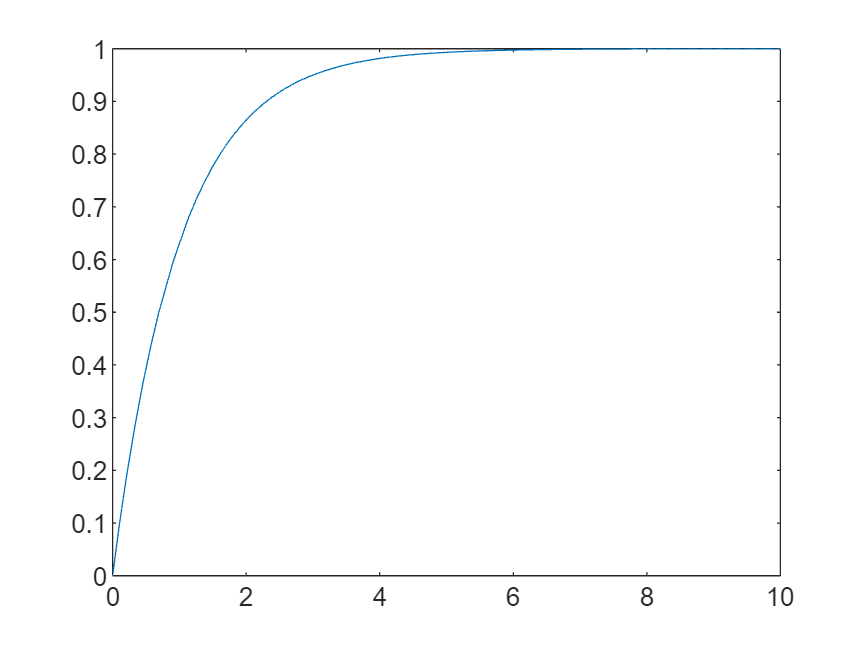

fplot(ans1b_example, [0, 10])

eq2 = subs(eq, u, K*(r-v))

$$eq2(t) = m\,\frac{\partial }{\partial t}v\left(t\right)=K\,\left(r-v\left(t\right)\right)-c\,v\left(t\right)$$

ans2b = dsolve(eq2, v(0)==0)

$$ans2b = \frac{K\,r-K\,r\,{\mathrm{e}}^{-\frac{t\,\left(K+c\right)}{m}}}{K+c}$$


ans2a = limit(ans2b, t, inf)

$$ans2a = \left\{ \begin{array}{cl} \frac{K\,r}{K+c} & \text{ if }0<K+c\vee r=0\\ -r\,\infty & \text{ if }K+c<0\wedge r\neq 0 \end{array}\right.$$

ans2b_example = subs(ans2b, [r, m, c, K],[1, 1, 1, 10])

$$ans2b\_example = \frac{10}{11}-\frac{10\,{\mathrm{e}}^{-11\,t}}{11}$$

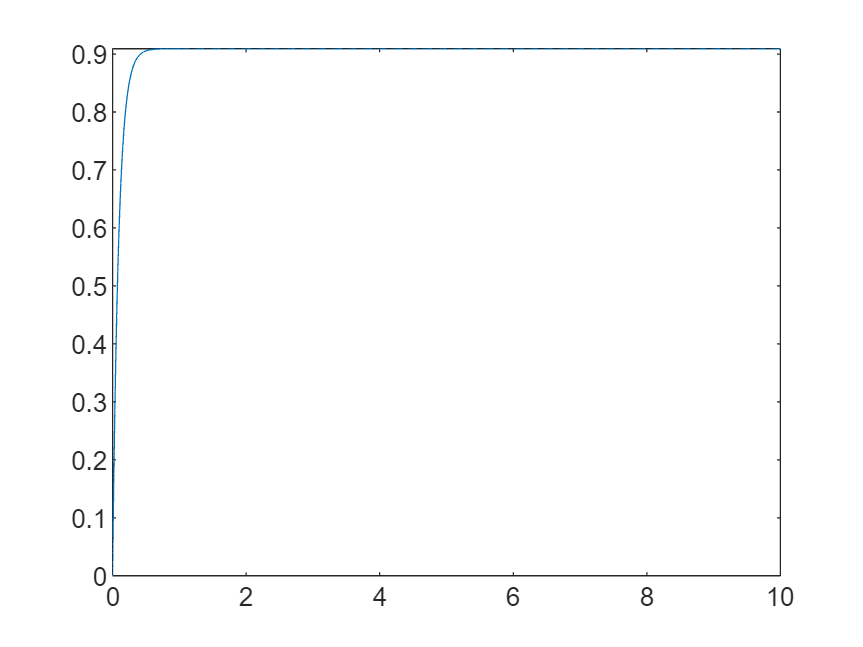

fplot(ans2b_example, [0, 10])